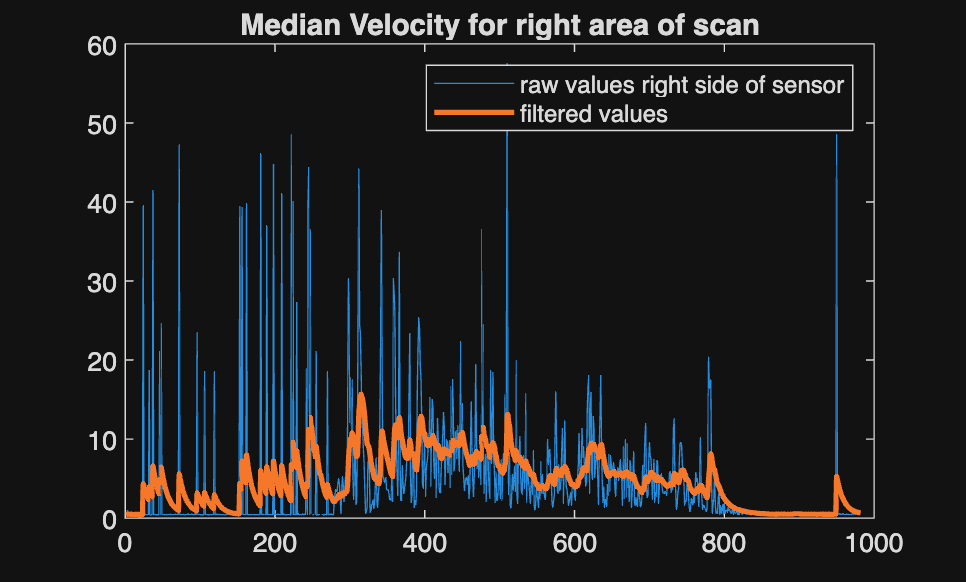

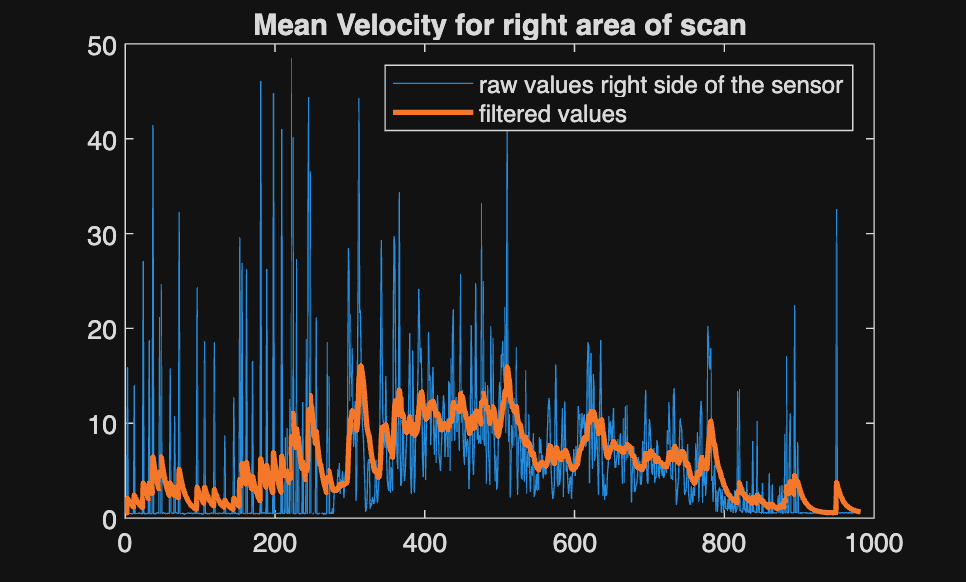

clc; clear; close all;

% change suffix from 1 to 5 to get different data files 

% filepath_r_scan = '/Users/madmel/Desktop/Bachelor/Data/25052026/25052026_scan_test_street_4.csv';
% filepath_xy_scan = '/Users/madmel/Desktop/Bachelor/Data/25052026/25052026_scan_xy_test_street_4.csv';
% filepath_vx_vy = '/Users/madmel/Desktop/Bachelor/Data/25052026/25052026_velocities_x_y_test_street_4.csv';

% ================================================== %
 
filepath_r_scan = '/Users/madmel/Desktop/Bachelor/Data/06062026/06062026_scan_test_3.csv';
filepath_xy_scan = '/Users/madmel/Desktop/Bachelor/Data/06062026/06062026_scan_xy_test_3.csv';
filepath_vx_vy = '/Users/madmel/Desktop/Bachelor/Data/06062026/06062026_velocities_x_y_test_3.csv';

% ===== for triming long measurements uncomment the function below ===== %

% trimLidarData(filepath_xy_scan , filepath_r_scan, filepath_vx_vy, 2880, 3400)

% ===== load data ===== %

[t_r_, r_all_, t_xy_, x_all_, y_all_, t_velocity, vx_all, vy_all, v] = loadData(filepath_xy_scan, filepath_r_scan, filepath_vx_vy);

% ===== keep only the values with proper velocity ( vel < 20 m/s and vel > 0 m/s) ===== % 

scanPointNumbers = 421; % files come with 421 points now, earlier measurements contained the full scan (811 points per scan)
[x_filtered, y_filtered, vx_filtered, vy_filtered, v_filtered, r_filtered]= filterAllValuesWithProperVelocities(x_all_, y_all_, vx_all, vy_all, v, r_all_, scanPointNumbers);
% filtered scans are now maticies, each row represents one scan, number of
% rows: number sf scans

% ===== define critical area ===== %  

[x_points_in_critical_area, y_points_in_critical_area, x_sensor_back, y_sensor_back] = ExtractPointsInCriticalArea(x_filtered, y_filtered); 

% ===== segmentation ===== % 

segments_side = findSegments(x_points_in_critical_area, y_points_in_critical_area);
segments_back = findSegments(x_sensor_back, y_sensor_back);

% ===== clustering ===== %

clusters_side = mergeSegmentsToClustersPerScan(segments_side);
clusters_back = mergeSegmentsToClustersPerScan(segments_back);

% ===== tracking ===== %

clusters_side_with_id = trackClustersBetweenScans(clusters_side);
clusters_back_with_id = trackClustersBetweenScans(clusters_back);

% ===== classification and direction of movement ===== %

object_side_properties = classifyClusters(clusters_side_with_id);  % objects: id, direction: object.approaching (true/false)
object_back_properties = classifyClusters(clusters_back_with_id);

% ===== velocities and egovelocity ===== %

[v_mean, v_median, point_index_median_velocities] = computeMeanMedianVelocity(v_filtered, r_filtered, scanPointNumbers);
[alphafiltered_median, alphafiltered_mean] = alphaFilter(v_median(:,1), v_mean(:,1)); % alpha filter to estimate the ego velocity

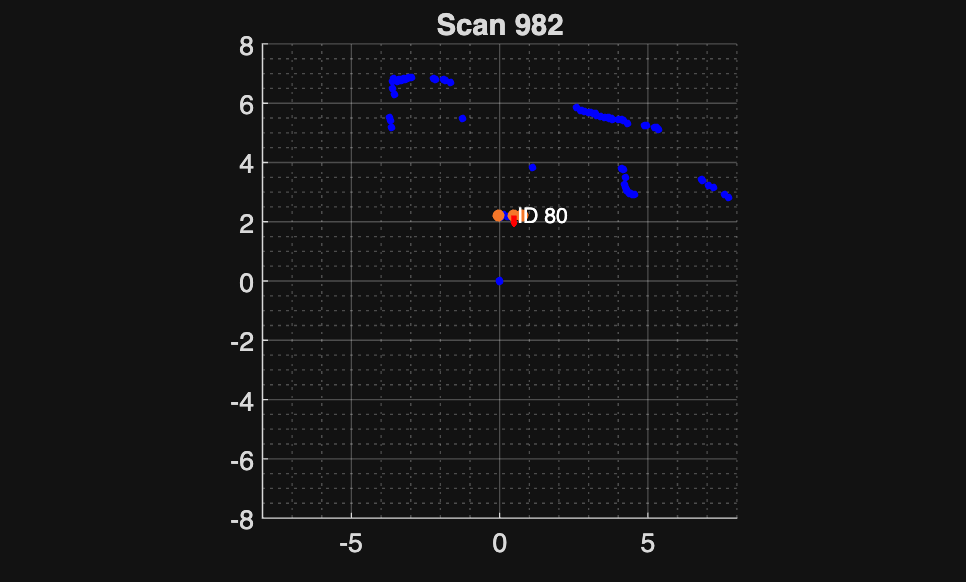


% ===== detection of potential dangerous situations ===== %

dangerousClustersSide = detectDangerousObjectSide(clusters_side_with_id, object_side_properties, alphafiltered_mean); 
dangerousClustersBack = detectDangerousObjectBack(clusters_back_with_id, object_back_properties, alphafiltered_mean);

% ===== final plot ===== %
plotObjects(x_filtered, y_filtered, clusters_back_with_id, object_back_properties, dangerousClustersSide, dangerousClustersBack);